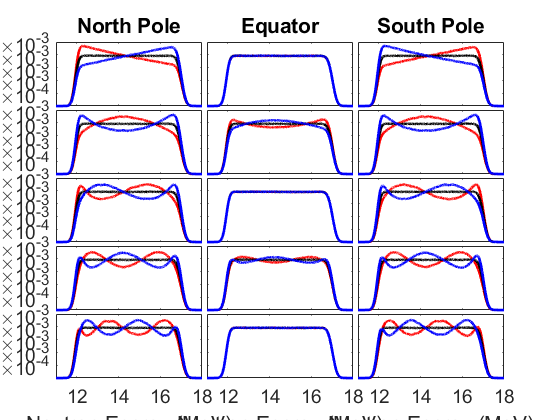

ans = '.'

ans = '..'

ans = 'license.txt'

ans = 'parseArgs.m'

ans = 'plotSimData.mlx'

ans = 'subaxis.m'

ans = 'subaxis.zip'

ans = 'tempDTn_Equator_1_-0.40.output'

ans = 'tempDTn_Equator_1_0.00.output'

ans = 'tempDTn_Equator_1_0.40.output'

ans = 'tempDTn_Equator_2_-0.40.output'

ans = 'tempDTn_Equator_2_0.00.output'

ans = 'tempDTn_Equator_2_0.40.output'

ans = 'tempDTn_Equator_3_-0.40.output'

ans = 'tempDTn_Equator_3_0.00.output'

ans = 'tempDTn_Equator_3_0.40.output'

ans = 'tempDTn_Equator_4_-0.40.output'

ans = 'tempDTn_Equator_4_0.00.output'

ans = 'tempDTn_Equator_4_0.40.output'

ans = 'tempDTn_Equator_5_-0.40.output'

ans = 'tempDTn_Equator_5_0.00.output'

ans = 'tempDTn_Equator_5_0.40.output'

ans = 'tempDTn_North Pole_1_-0.40.output'

ans = 'tempDTn_North Pole_1_0.00.output'

ans = 'tempDTn_North Pole_1_0.40.output'

ans = 'tempDTn_North Pole_2_-0.40.output'

ans = 'tempDTn_North Pole_2_0.00.output'

ans = 'tempDTn_North Pole_2_0.40.output'

ans = 'tempDTn_North Pole_3_-0.40.output'

ans = 'tempDTn_North Pole_3_0.00.output'

ans = 'tempDTn_North Pole_3_0.40.output'

ans = 'tempDTn_North Pole_4_-0.40.output'

ans = 'tempDTn_North Pole_4_0.00.output'

ans = 'tempDTn_North Pole_4_0.40.output'

ans = 'tempDTn_North Pole_5_-0.40.output'

ans = 'tempDTn_North Pole_5_0.00.output'

ans = 'tempDTn_North Pole_5_0.40.output'

ans = 'tempDTn_South Pole_1_-0.40.output'

ans = 'tempDTn_South Pole_1_0.00.output'

ans = 'tempDTn_South Pole_1_0.40.output'

ans = 'tempDTn_South Pole_2_-0.40.output'

ans = 'tempDTn_South Pole_2_0.00.output'

ans = 'tempDTn_South Pole_2_0.40.output'

ans = 'tempDTn_South Pole_3_-0.40.output'

ans = 'tempDTn_South Pole_3_0.00.output'

ans = 'tempDTn_South Pole_3_0.40.output'

ans = 'tempDTn_South Pole_4_-0.40.output'

ans = 'tempDTn_South Pole_4_0.00.output'

ans = 'tempDTn_South Pole_4_0.40.output'

ans = 'tempDTn_South Pole_5_-0.40.output'

ans = 'tempDTn_South Pole_5_0.00.output'

ans = 'tempDTn_South Pole_5_0.40.output'

clear all;
figure; hold on; box on;
files = dir();


for i = 1:length(files)
    
    files(i).name
    
    if contains(files(i).name, ".output")
        
        if contains(files(i).name, "North Pole")
            j = 1;
        elseif contains(files(i).name, "Equator")
            j = 2;
        elseif contains(files(i).name, "South Pole")
            j = 3;
        end
        
        if contains(files(i).name, "_1_")
            k = 1;
        elseif contains(files(i).name, "_2_")
            k = 2;
        elseif contains(files(i).name, "_3_")
            k = 3;
        elseif contains(files(i).name, "_4_")
            k = 4;
        elseif contains(files(i).name, "_5_")
            k = 5;
        end
        
        if contains(files(i).name, "_0.00")
            color = 'k';
        elseif contains(files(i).name, "_-0.40")
            color = 'r';
        elseif contains(files(i).name, "_0.40")
            color = 'b';
        end
        
        
        data = getData(files(i).name);
        subaxis(5,3,3*(k-1) + j, 'Spacing', 0.01); hold on; box on;
        xlim([11, 18])
        ylim([1e-16 2.5e-3])
        temp = gca;
        temp.YAxis.Exponent = 0;
        ytickformat('%.1e')
        set(gca, 'FontSize', 14)
        plot(data.energy, data.value./sum(data.value), 'DisplayName',files(i).name, 'LineWidth', 2, 'Color', color)
        
        if j == 1
            ylabel('Yield Ratio per Bin')
        else
            set(gca, 'YTickLabel', [])
        end
        
        if k == 5
            xlabel('Neutron Energy (MeV)')
        else
            set(gca, 'XTickLabel', [])
        end
        
        if k == 1
            if j == 1
                title('North Pole')
            elseif j == 2
                title('Equator')
            elseif j == 3
                title('South Pole')
            end          
        end
        
    end
end

function data = getData(filename)

    file = fopen(filename);
    while ~feof(file)
        
        line = fgetl(file);
        
        if contains(line, "--- Birth Spectrum Tally ---")
            
            line = fgetl(file);
            line = fgetl(file);
            line = fgetl(file);
            
            energy = []; value = []; unc = [];
            done = false;
            while ~done
                
               temp = strsplit(line, ",");
               
               energy(end+1) = str2double(temp{1});
               value(end+1)  = str2double(temp{2});
               unc(end+1)    = str2double(temp{3});
               
               line = fgetl(file);
               done = contains(line, "total");
               
            end
        end
    end
    
    fclose(file);
    
    data = [];
    data.energy = energy;
    data.value = value;
    data.unc = unc;

end